Narxnet

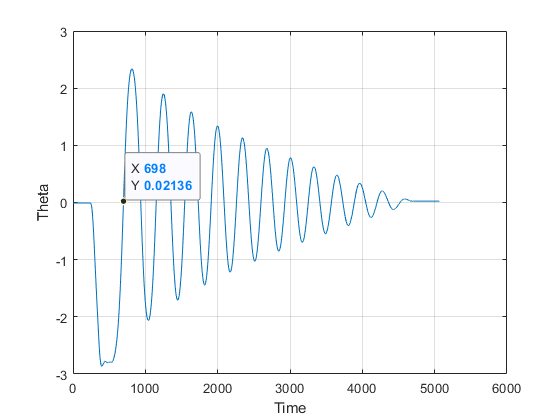

theta = dane_NN_test2.signals(1).values;
time = dane_NN_test2.time;

figure
plot(theta)
xlabel('Time')
ylabel('Theta')
grid on

y_begin_sample = 702;
y_end_sample = 4802;


training_data_input_1 = theta(y_begin_sample-2:y_end_sample-2)

training_data_input_1 =     0.0971
    0.1348
    0.1725
    0.2099
    0.2472
    0.2846
    0.3220
    0.3588
    0.3958
    0.4323


training_data_input_2 = theta(y_begin_sample-1:y_end_sample-1)

training_data_input_2 =     0.1348
    0.1725
    0.2099
    0.2472
    0.2846
    0.3220
    0.3588
    0.3958
    0.4323
    0.4687


training_data_output = theta(y_begin_sample:y_end_sample)

training_data_output =     0.1725
    0.2099
    0.2472
    0.2846
    0.3220
    0.3588
    0.3958
    0.4323
    0.4687
    0.5049


time_train = (time(y_begin_sample:y_end_sample) - time(y_begin_sample))'

time_train =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900



%wyjscie jest wejściem 
x_train = training_data_output'

x_train =     0.1725    0.2099    0.2472    0.2846    0.3220    0.3588    0.3958    0.4323    0.4687    0.5049    0.5410    0.5765    0.6120    0.6475    0.6824    0.7172    0.7518    0.7860    0.8200    0.8536    0.8869    0.9205    0.9532    0.9852    1.0166    1.0487    1.0798    1.1106    1.1410    1.1712    1.2007    1.2302    1.2592    1.2881    1.3160    1.3440    1.3710    1.3980    1.4244    1.4508    1.4762    1.5017    1.5268    1.5513    1.5755    1.5991    1.6223    1.6453    1.6676    1.6895


inputSeries = num2cell(x_train)

inputSeries = 1×4101 cell array
  Columns 1 through 695

    {[0.1725]}    {[0.2099]}    {[0.2472]}    {[0.2846]}    {[0.3220]}    {[0.3588]}    {[0.3958]}    {[0.4323]}    {[0.4687]}    {[0.5049]}    {[0.5410]}    {[0.5765]}    {[0.6120]}    {[0.6475]}    {[0.6824]}    {[0.7172]}    {[0.7518]}    {[0.7860]}    {[0.8200]}    {[0.8536]}    {[0.8869]}    {[0.9205]}    {[0.9532]}    {[0.9852]}    {[1.0166]}    {[1.0487]}    {[1.0798]}    {[1.1106]}    {[1.1410]}    {[1.1712]}    {[1.2007]}    {[1.2302]}    {[1.2592]}    {[1.2881]}    {[1.3160]}    {[1.3440]}    {[1.3710]}    {[1.3980]}    {[1.4244]}    {[1.4508]}    {[1.4762]}    {[1.5017]}    {[1.5268]}    {[1.5513]}    {[1.5755]}    {[1.5991]}    {[1.6223]}    {[1.6453]}    {[1.6676]}    {[1.6895]}    {[1.7112]}    {[1.7323]}    {[1.7530]}    {[1.7734]}    {[1.7935]}    {[1.8130]}    {[1.8322]}    {[1.8510]}    {[1.8692]}    {[1.8872]}    {[1.9047]}    {[1.9220]}    {[1.9387]}    {[1.9553]}    {[1.9710]}    {[1.9867]}    {[2.0021]}    {

targetSeries = num2cell(x_train)

targetSeries = 1×4101 cell array
  Columns 1 through 695

    {[0.1725]}    {[0.2099]}    {[0.2472]}    {[0.2846]}    {[0.3220]}    {[0.3588]}    {[0.3958]}    {[0.4323]}    {[0.4687]}    {[0.5049]}    {[0.5410]}    {[0.5765]}    {[0.6120]}    {[0.6475]}    {[0.6824]}    {[0.7172]}    {[0.7518]}    {[0.7860]}    {[0.8200]}    {[0.8536]}    {[0.8869]}    {[0.9205]}    {[0.9532]}    {[0.9852]}    {[1.0166]}    {[1.0487]}    {[1.0798]}    {[1.1106]}    {[1.1410]}    {[1.1712]}    {[1.2007]}    {[1.2302]}    {[1.2592]}    {[1.2881]}    {[1.3160]}    {[1.3440]}    {[1.3710]}    {[1.3980]}    {[1.4244]}    {[1.4508]}    {[1.4762]}    {[1.5017]}    {[1.5268]}    {[1.5513]}    {[1.5755]}    {[1.5991]}    {[1.6223]}    {[1.6453]}    {[1.6676]}    {[1.6895]}    {[1.7112]}    {[1.7323]}    {[1.7530]}    {[1.7734]}    {[1.7935]}    {[1.8130]}    {[1.8322]}    {[1.8510]}    {[1.8692]}    {[1.8872]}    {[1.9047]}    {[1.9220]}    {[1.9387]}    {[1.9553]}    {[1.9710]}    {[1.9867]}    {[2.0021]}    


net = narxnet(1:2, 1, 2);
[Xs,Xi,Ai,Ts] = preparets(net,targetSeries,{},inputSeries)

Xs = 2×4099 cell array
  Columns 1 through 695

    {[0.2472]}    {[0.2846]}    {[0.3220]}    {[0.3588]}    {[0.3958]}    {[0.4323]}    {[0.4687]}    {[0.5049]}    {[0.5410]}    {[0.5765]}    {[0.6120]}    {[0.6475]}    {[0.6824]}    {[0.7172]}    {[0.7518]}    {[0.7860]}    {[0.8200]}    {[0.8536]}    {[0.8869]}    {[0.9205]}    {[0.9532]}    {[0.9852]}    {[1.0166]}    {[1.0487]}    {[1.0798]}    {[1.1106]}    {[1.1410]}    {[1.1712]}    {[1.2007]}    {[1.2302]}    {[1.2592]}    {[1.2881]}    {[1.3160]}    {[1.3440]}    {[1.3710]}    {[1.3980]}    {[1.4244]}    {[1.4508]}    {[1.4762]}    {[1.5017]}    {[1.5268]}    {[1.5513]}    {[1.5755]}    {[1.5991]}    {[1.6223]}    {[1.6453]}    {[1.6676]}    {[1.6895]}    {[1.7112]}    {[1.7323]}    {[1.7530]}    {[1.7734]}    {[1.7935]}    {[1.8130]}    {[1.8322]}    {[1.8510]}    {[1.8692]}    {[1.8872]}    {[1.9047]}    {[1.9220]}    {[1.9387]}    {[1.9553]}    {[1.9710]}    {[1.9867]}    {[2.0021]}    {[2.0172]}    {[2.0314]}    {[2.0458]}

Xi = 2×2 cell array
    {[0.1725]}    {[0.2099]}
    {[0.1725]}    {[0.2099]}



Ai =

  2×0 empty cell array



Ts = 1×4099 cell array
  Columns 1 through 695

    {[0.2472]}    {[0.2846]}    {[0.3220]}    {[0.3588]}    {[0.3958]}    {[0.4323]}    {[0.4687]}    {[0.5049]}    {[0.5410]}    {[0.5765]}    {[0.6120]}    {[0.6475]}    {[0.6824]}    {[0.7172]}    {[0.7518]}    {[0.7860]}    {[0.8200]}    {[0.8536]}    {[0.8869]}    {[0.9205]}    {[0.9532]}    {[0.9852]}    {[1.0166]}    {[1.0487]}    {[1.0798]}    {[1.1106]}    {[1.1410]}    {[1.1712]}    {[1.2007]}    {[1.2302]}    {[1.2592]}    {[1.2881]}    {[1.3160]}    {[1.3440]}    {[1.3710]}    {[1.3980]}    {[1.4244]}    {[1.4508]}    {[1.4762]}    {[1.5017]}    {[1.5268]}    {[1.5513]}    {[1.5755]}    {[1.5991]}    {[1.6223]}    {[1.6453]}    {[1.6676]}    {[1.6895]}    {[1.7112]}    {[1.7323]}    {[1.7530]}    {[1.7734]}    {[1.7935]}    {[1.8130]}    {[1.8322]}    {[1.8510]}    {[1.8692]}    {[1.8872]}    {[1.9047]}    {[1.9220]}    {[1.9387]}    {[1.9553]}    {[1.9710]}    {[1.9867]}    {[2.0021]}    {[2.0172]}    {[2.0314]}    {[2.0458]}

net = train(net,Xs,Ts,Xi,Ai);

[y_net,Xf,Af] = net(Xs,Xi,Ai);
y_net = cell2mat(y_net)

y_net =     0.2471    0.2845    0.3218    0.3592    0.3953    0.4327    0.4685    0.5049    0.5407    0.5768    0.6117    0.6472    0.6827    0.7169    0.7518    0.7860    0.8199    0.8535    0.8868    0.9198    0.9537    0.9855    1.0169    1.0477    1.0803    1.1105    1.1409    1.1711    1.2010    1.2299    1.2594    1.2877    1.3166    1.3436    1.3715    1.3976    1.4246    1.4504    1.4768    1.5013    1.5268    1.5516    1.5755    1.5993    1.6223    1.6452    1.6678    1.6895    1.7112    1.7326


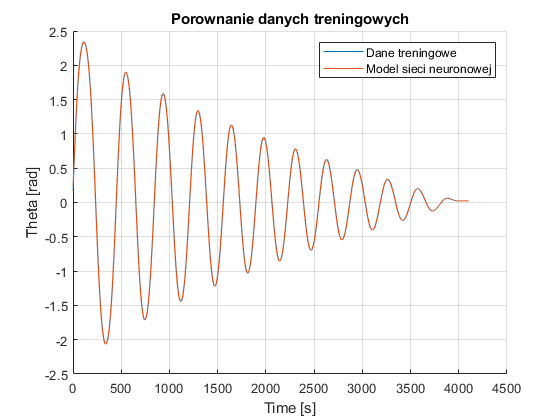



figure();
hold on
plot(training_data_output)
plot(y_net)
hold off
legend("Dane treningowe", 'Model sieci neuronowej')
xlabel('Time [s]')
ylabel('Theta [rad]')
title('Porownanie danych treningowych')
grid on

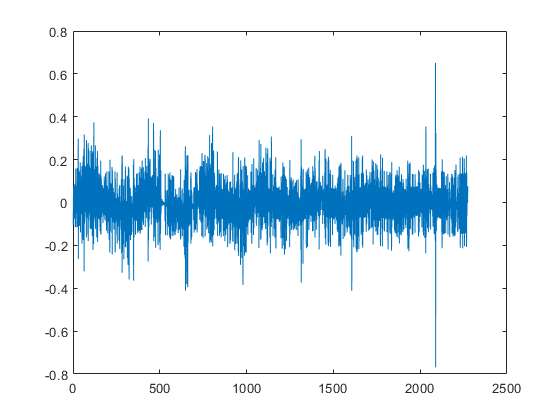


% err = immse(y_train, y_net)
% err = y_net-y_train
% err_degree = err * 180/pi
% figure;
% plot(err)

figure;
plot(err_degree)